# Local Basis Function Representations of Thermodynamic Surfaces 

# by J.Michael Brown

This script provides examples of fitting data as a function of 1, 2 or 3 independent variables using the function "spdft" (**sp**line **d**ata **f**it**t**er).  The function allows use of any order tensor b spline with an  arbitrary (uniform or non-uniform) distributions  of "control points" (these points determine the intervals between knots used in construction of b splines). The use of  "regularization" allows fitting of data that may not adequately span the model parameter space (either because regions within the range of data may be under-sampled or because the representation is used in extrapolation). Through regularization, a specified derivative of the model is required to be "small". A typical choice is to require small second derivatives such that the fit is "smooth".

Usage:   **sp=spdft(X,Y,dY,options)**

The input (X and Y) can be gridded or scattered and can be of variable (2, 3, or 4) dimensions.  Gridded data are entered as cells (a vector for each independent variable).  Scattered data are entered as matrixes with a column for each independent variable and a row for each data point.  

**X** contains independent variables (matrix or cell), **Y **is the dependent variable (a vector),  **dY **contains data uncertainties.  (1) If **dY **is empty, the standard deviation of Y is used to normalize the data, (2) If **dY** is a scalar, the same uncertainty is assigned to all data, (3) If **dY** is a vector  (same size as Y) individual uncertainties are assigned to each data point

The following input options are entered within the structure "options"

- **Xc** (vector or cell-if more than one independent variable) are the "control points" used to determine knot locations. If Xc is not provided and X is a cell, Xc is set to X

- **lam** is a vector of smoothing parameters (one for each independent variable).   If lam is not provided,  values are set to 1

- **RegFac** is a vector of integers for the regularization oversampling (number of regularization points between each control point).  (1) if RegFac is not included in options, the default  is 1 for all dimensions.  (2) if RegFac is included as an empty vector, a least square fit without regularization is attempted (this is likely to fail unless data coverage is adequate)      

- **ordr** is a vector of integers defining the spline order for each independent variable. If ordr is not provided the order is set to  4 for all dimensions

- **mdrv** is a vector of integers defining which derivative is to be  minimized.  If mdrv is not provided, the default is set to 2 (make a smooth fit)

- **mask** is a list of ones or nan to specify which data to exclude from the fit.  If mask is not provided, all values of mask are set to 1 - all data are fit. This  feature is important for thermodyamic surfaces where metastable regions must be "masked-off" (not included in the fit since properties are not known there)

- ** algorithm ** sets the method of solution.  The default is to solve a set of "normal equations" .  If algorithm is present in the options structure, a "Least Square"  solution is undertaken.  This does not usually make any difference since solvers have become robust in either case.  The Least Square algorithm can be much slower for some large problems.

spdft requires functions from the matlab spline (curve fitting) toolbox.  Custom function mkCmn mkgrid area_wt are nested within the function.

Three examples are shown below:

- fitting with a single independent variable

- fitting with two independent variables

- fitting with three independent variables

## Fitting a Set of x-y Data (a single independent variable). 

Data for the independent variable, X, extend from 0 to 60 but the LBF representation is determined to 100 to show behavior in extrapolation.  The example data are "hard" to fit with conventional polynomials since second derivatives are large and variable for small X and smaller for larger X. Many polynomial terms would be required to follow the small X behavior while showing less variation for larger X.  A range of damping values is used - from overdamped (essentially a linear fit to data) to underdamped (over fitting data) - notice that damping=1 achieves a reduced chi square near 1.  Note also that the fit in the extrapolated region has zero second derivatives. Regularization in the absence of data controls the nature of the fit in the region of extrapolation.

% Here are trial data to fit:
data2fit=XY2fit_data;
X1=data2fit(:,1);
Y1=data2fit(:,2);
uncert=.05;  % set constant data uncertainty - can be vector or empty


 Below here, the spline fitting parameters are described. One must:

      1. define control points, 

      2. determine how many regularization points per control point (1 is a typical value)

      3. specify the order of the spline, 

      4. specify what derivative to minimize,

      5. specify what damping factor to use

For small control point spacings,  the fit should be insensitive to spacing choice.  If the spacings are too wide, the piece-wise polynomials will not have sufficient flexibility to fit  the data.  By experimentation, it is possible to test this.  The control point spacing is initially set to 1 below.  Larger control point spacing results in under-fitting the data even for small values of damping (the low order piece-wise polynomials cannot follow the trends on large intervals).  Smaller values for the control point spacing do not change the quality of the fit but do result in a model with more (unnecessary) parameters.

dx=.1;  % try .1 .5 1 2 5 10 
clear options%clear to insure that previously set properties are not inadvertently used
options.Xc=0:dx:100;  % the spline control points are set

Since other options are not set, default values are used.  Commented lines below show examples if other options need to be modified.

% options.RegFac=1;  % chose amount of over-sampling of regularization 
%                    empty for no regularization 
%                    1 for 1 regularization point per control point
% options.ordr=4;    % increasing the spline order can compensate for wider control
%                    point spacing (try orders between 4 (minimum for smoothing) 
%                    and 10 with larger or smaller dx values)
% options.mdrv=2;    % here a smooth fit requires minimizing the second derivative 
%                       of the fit:

Try a range of damping factors - near 1 is always a place to start

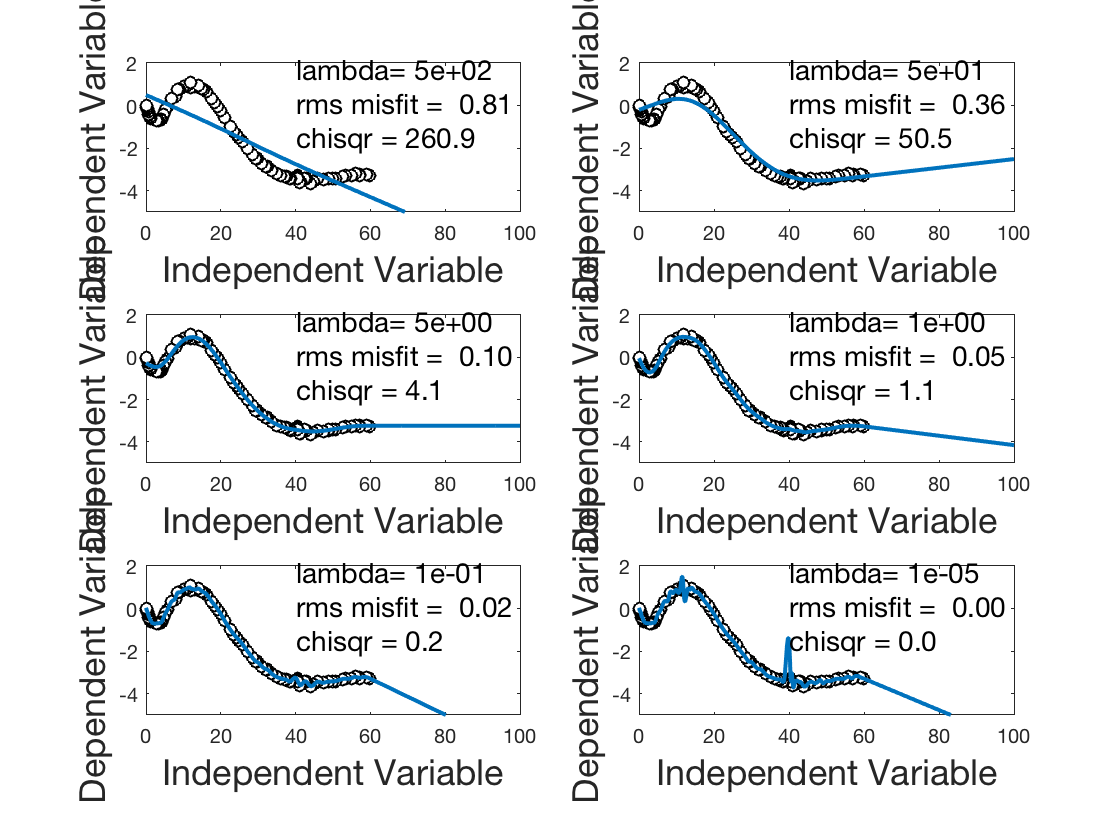

lam=[ 500 50 5 1 .1 1e-5 ];
for i=1:length(lam)
    options.lam=lam(i);
    subplot(3,2,i)  

    Here is the call to the spline fitting function:

    sp1=spdft(X1,Y1,uncert,options);

 spdft puts fit statistics into the returned spline structure - pull them out and create a text for the plots:

txt=sprintf('lambda= %4.0e \nrms misfit = %5.2f \nchisqr = %3.1f',...
                 lam(i),sp1.Data.rms,sp1.Data.chisqr);
plot(X1,Y1,'ko','MarkerFaceColor','w')
    hold on
    fnplt(sp1) % fnplt is a MATLAB utility for quickly plotting spline representations
    text(40,.1,txt,'FontSize',14)
    xlabel('Independent Variable','FontSize',18)
    ylabel('Dependent Variable ','FontSize',18)
    axis([0 100 -5 2 ])
    hold off
end

Examples of fitting data with one independent variable. A smoothing regularization is applied to a cubic spline representation. The "smoothing" is controlled by the damping lambda which, in the separate panels, is varied by many orders of magnitude.  Too much damping results in a linear least-squares fit (upper left).  Too little damping (lower right) results in over-fitting the data (a reduced chi-square that is much less than 1 and clear evidence of instability of the model between data points). Here a damping factor of 1 results in a curve with a reduced chi-square misfit of 1.1 that is also visually consistent with data.

## Fitting a Set of x-y-z Data (two independent variables). 

The  Lin and Trusler (2012) sound speeds for pure water are fit as a function of  pressure and temperature  

LT=LT_data;  % this function returns the Lin and Trusler data set.

Chose the number of control points for P and T and set the grid of control points

npc=15;  % adjust this to change the numbers of pressure control points
ntc=15;  % adjust this to change the numbers of temperature control points
Xc=linspace(0,500,npc);
Yc=linspace(240,500,ntc);
clear options
options.Xc={Xc,Yc};

The values given below were manually adjusted to achieve a reduced chi square of about 1. Change these numbers to see the effect on misfits and smoothness of the resulting surface smaller values for less misfit and less "smoothness", larger values for greater misfit and smoothness

options.lam=[150 30];

All other options are allowed to be the default values.  Since data are scattered, input X is a matrix with as many columns as independent variables

sp2=spdft(LT(:,1:2),LT(:,3),LT(:,4),options);

examine fit with plots of data and surface and the misfits of the data from the surface

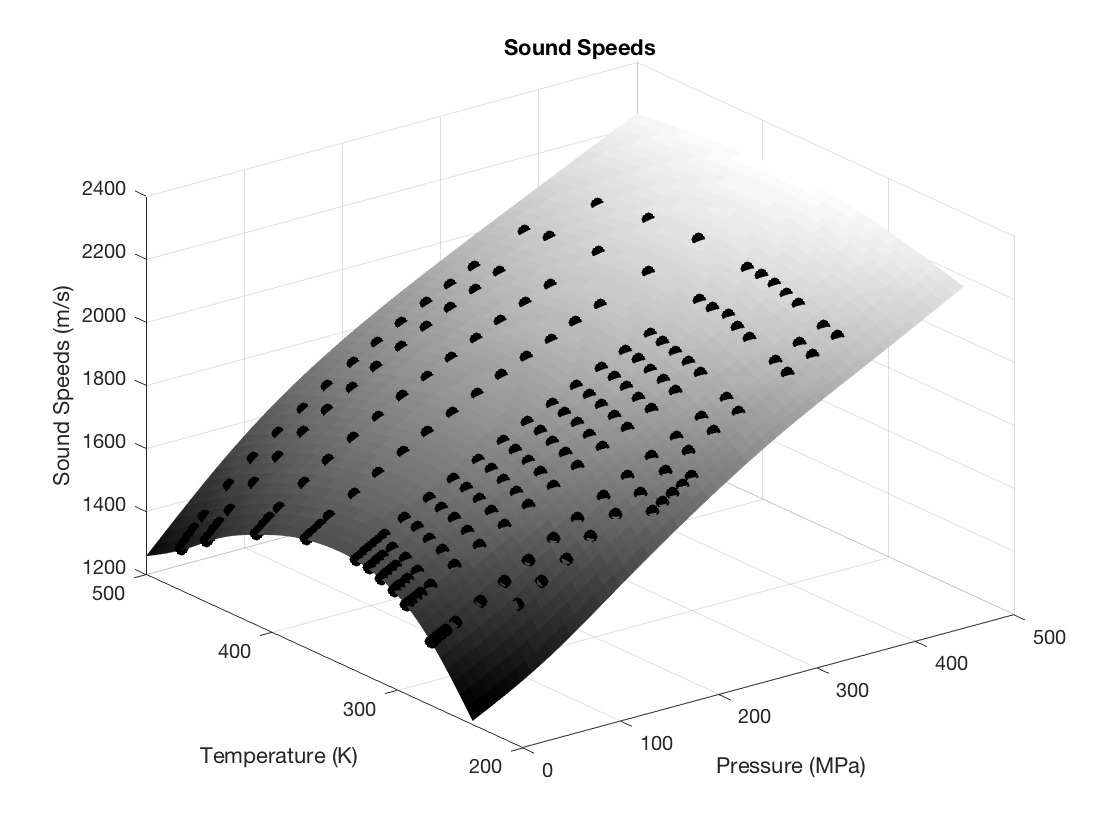

txt=sprintf('rms misfit = %5.2f m/s   chisqr = %5.2f',sp2.Data.rms,sp2.Data.chisqr);
subplot(111)
clf
fnplt(sp2)

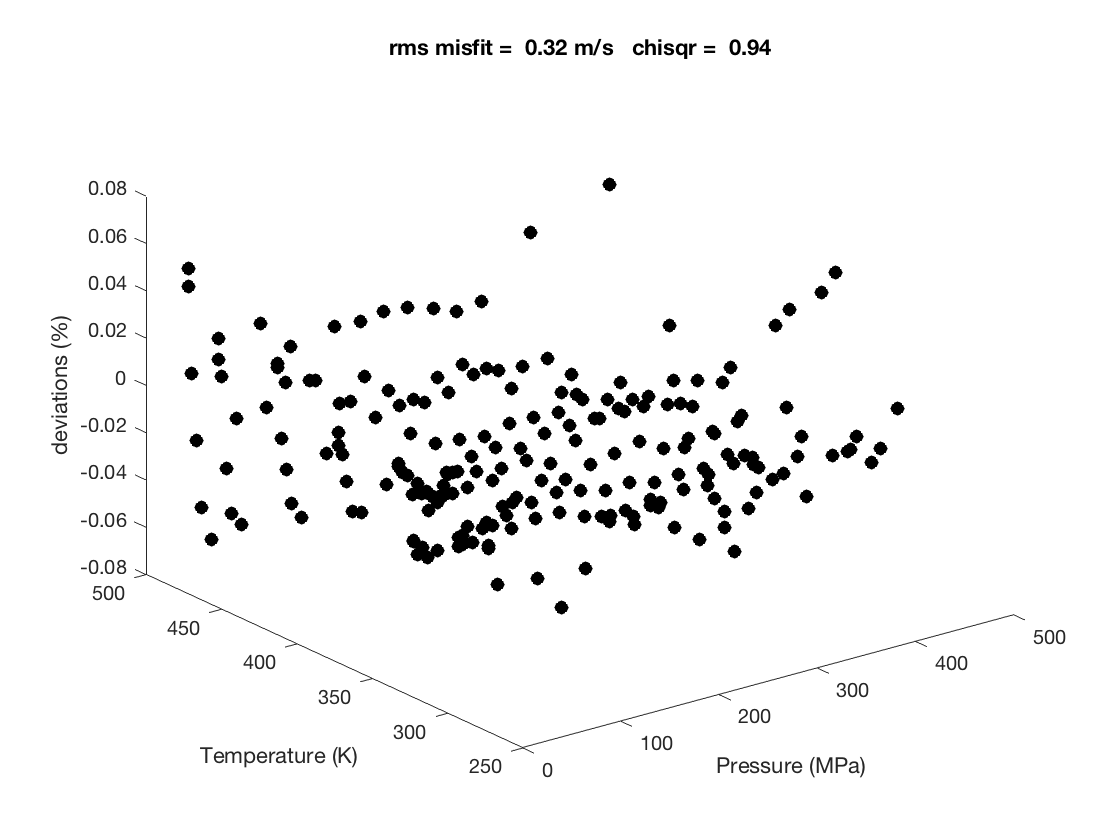

colormap gray
shading 'flat'
hold on
plot3(LT(:,1),LT(:,2),LT(:,3),'ko','MarkerFaceColor','k')
xlabel('Pressure (MPa)')
ylabel('Temperature (K)')

zlabel('Sound Speeds (m/s)')
hold off
title('Sound Speeds')

A local basis function (LBF) derived surface as a function of pressure and temperature is shown along with the sound speed measurements for water of Lin and Trusler (black circles). The surface follows the trend of the data smoothly and extrapolates reasonably in regions with no data.

plot3(LT(:,1),LT(:,2),1e2*(sp2.Data.devs)./LT(:,3),'ko','MarkerFaceColor','k')
xlabel('Pressure (MPa)')
ylabel('Temperature (K)')
zlabel('deviations (%)')
title(txt)

Sound speed misfits from the LBF representationas a function of pressure and temperature for the Lin and Trusler data. For the specified level of "damping" misfits are in the range of a few hundreth's of a percent and the reduced chi-square is appropriately near 1.  Smaller values for options.lam would result in smaller misfit with the reduced chi-square being less than 1 (data then being over-fit).  Larger vales of damping would result in a smoother surface that did not adequately fit the data.

## Fitting a Set of x-y-z-w Data (three independent variables). 

The .mat file MgSO4Data.mat contains  "P" "T" "m" "v" "dv"  vectors of scattered data including results in Vance and Brown (2013)  and other literature reported values including IAPWS for pure water below 400 MPa. Pressures are in MPa, T in K, m in mol/kg, and v and dv in km/s.

Vance, S, and Brown, J. M. (2013) Thermodynamic properties of aqueous MgSO4 to 800 MPa at temperatures for -20 to 100°C and concentrations to 2.5 mol/kg from sound speeds with applications to icy world oceans, Geochem. Cosmo. Acta, 110, 176–189

load MgSO4Data.mat
dv=.0025*v(:);
id=find(m(:)==0);
dv(id)=dv(id)/2;

Only damping and control points are specified - all other options are default values

clear options
options.lam=[500 10 1];

Here control points in P T and molality are set

Tc=240:20:380;
Pc=0:50:800;
mc=[0:.5:3];
options.Xc={Pc,Tc,mc};

Do the fit (note that the independent variables are input as a matrix that is 3 wide (P,T,m) and has a many rows as data points)

sp_ptm=spdft([P(:) T(:) m(:)],v(:),dv(:),options);


Calculate deviations of data from the surface

vc=fnval(sp_ptm,[P(:) T(:) m(:)]');
devs=100*(v-vc)./v;

Set up a plotting grid:

mplt=[0 .08 .51 .997 1.51 2.02]; % approximate compositions represented in the data
Pplt=0:50:800;
Tplt=240:10:380;

Calculate the sound speed surface on the plotting grid

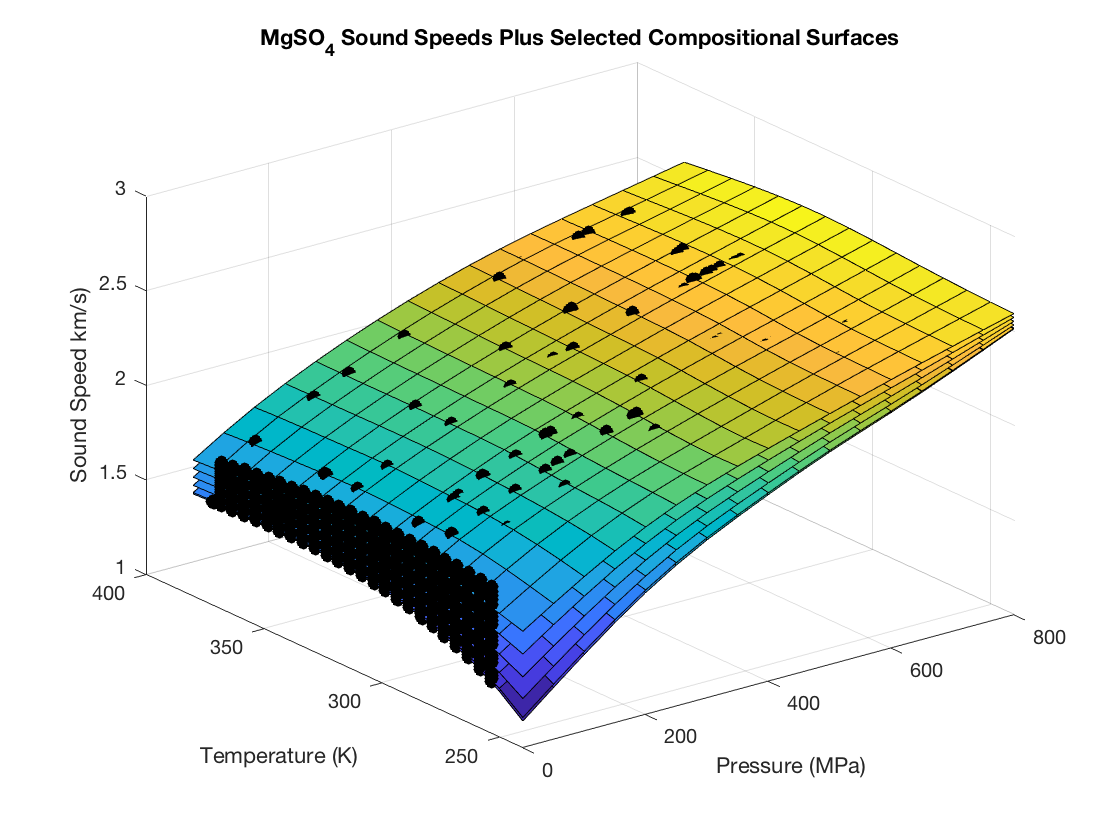

vplt=fnval(sp_ptm,{Pplt,Tplt,mplt});
subplot(111)
clf
for i=1:6
    surf(Pplt,Tplt,squeeze(vplt(:,:,i))') 
    hold on
end
plot3(P,T,v,'ko','MarkerFaceColor','k')
hold off
xlabel('Pressure (MPa)')
ylabel('Temperature (K)')
zlabel('Sound Speed km/s)')

title('MgSO_4 Sound Speeds Plus Selected Compositional Surfaces')

Sound speed data for $\mathrm{MgS}{\mathrm{O}}_4$(black circles) and surfaces based on a LBF representation as a function of pressure, temperature, and composition (m= 0  0.08 0.51 0.997 1.51 and 2.02 mol/kg) plotted as a function of pressure and temperature.

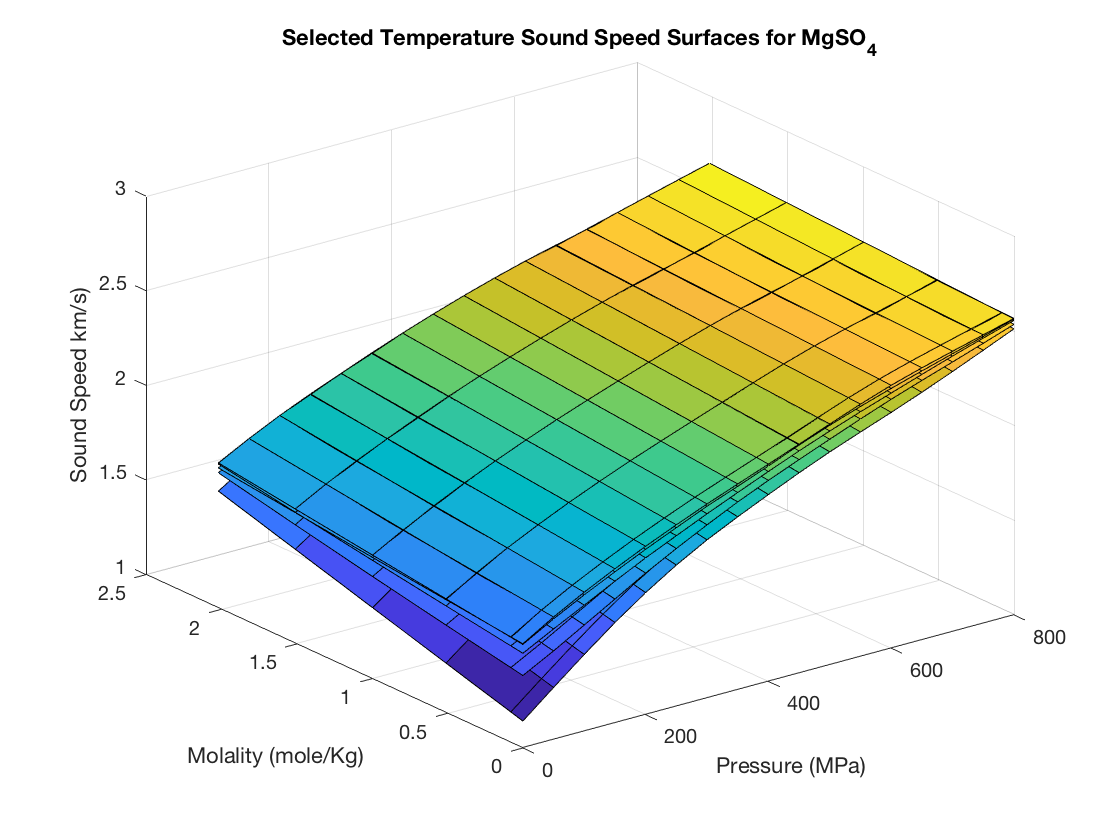

nt=length(Tplt);
for i=1:3:nt
    surf(Pplt,mplt,squeeze(vplt(:,i,:))')
    hold on
end
hold off
xlabel('Pressure (MPa)')
ylabel('Molality (mole/Kg)')
zlabel('Sound Speed km/s)')
title('Selected Temperature Sound Speed Surfaces for MgSO_4')

Isothermal surfaces (T=240 260 290 330 360 K) based on the LBF representation for $\mathrm{MgS}{\mathrm{O}}_4$ as a function pressure and composition

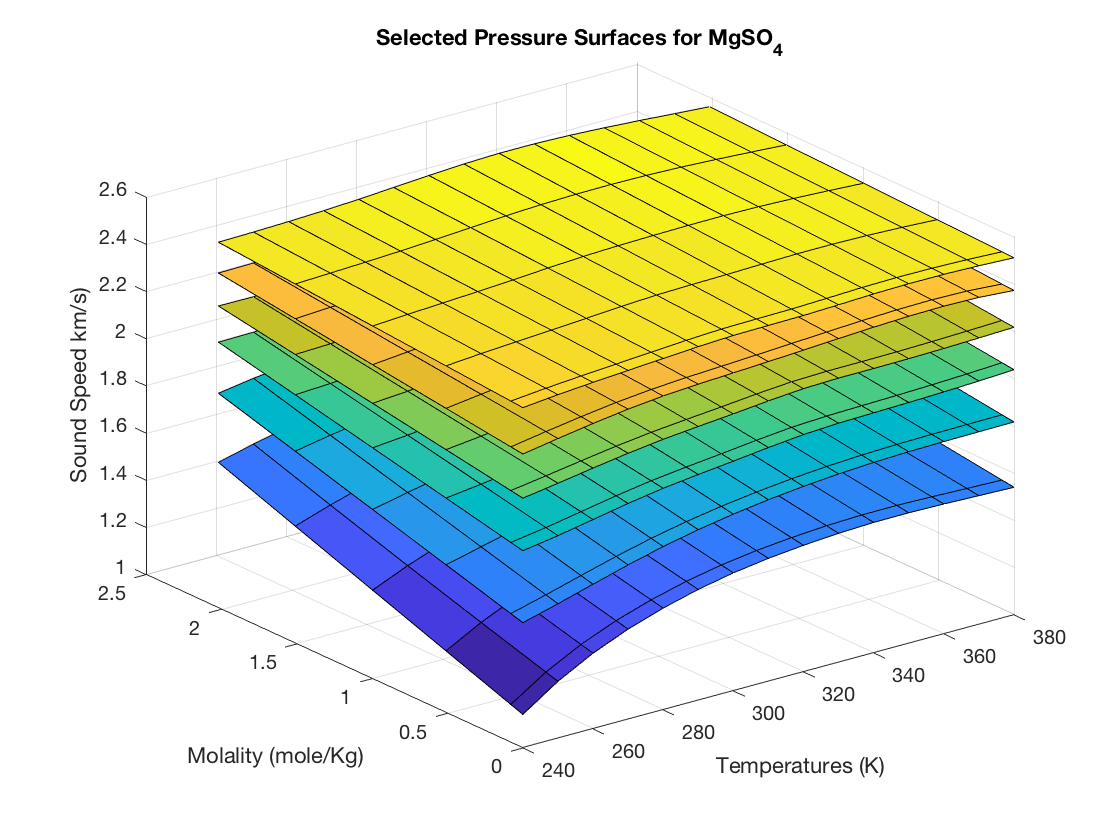

np=length(Pplt);
for i=1:3:np
    surf(Tplt,mplt,squeeze(vplt(i,:,:))')
    hold on
end
hold off
xlabel('Temperatures (K)')
ylabel('Molality (mole/Kg)')
zlabel('Sound Speed km/s)')
title('Selected Pressure Surfaces for MgSO_4')

Isobaric surfaces (P=0 100 250 400 550 700 MPa) based on the LBF representation for $\mathrm{MgS}{\mathrm{O}}_4$ as a function of temperature and composition.

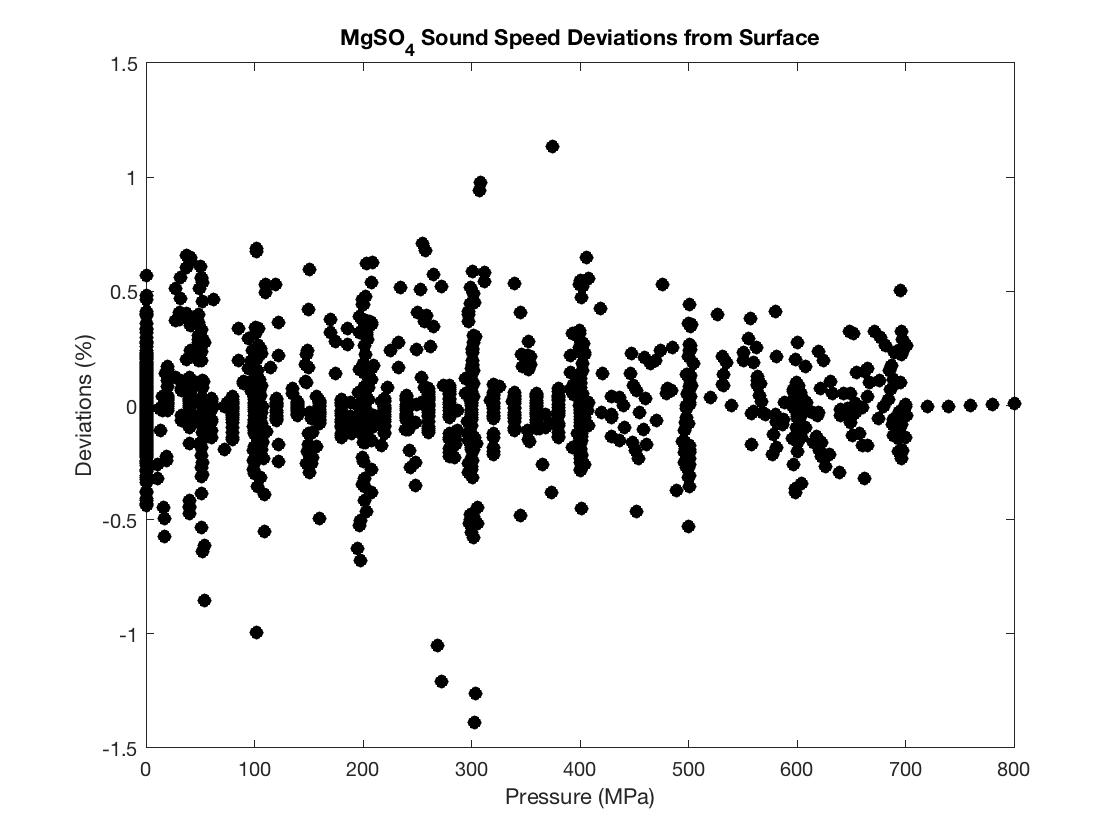

plot(P,devs,'ko','MarkerFaceColor','k')
xlabel('Pressure (MPa)')
ylabel('Deviations (%)')
title('MgSO_4 Sound Speed Deviations from Surface')

Percentage deviations from the LBF representation for all $\mathrm{MgS}{\mathrm{O}}_4$data (all temperatures and compositions) shown as a function of pressure. The rms misfit for the Vance and Brown data is about 0.3% which is a reasonable match to expectations for experimental uncertainty.